%% Enhanced Random Forest Fault Detection System
% Run this script directly in MATLAB

clear; clc; close all;

%% Global Variables for GUI
global rfModel XTrain YTrain XTest YTest featureNames mu sigma fig

%% Main Script Execution
disp('Fault Detection System');

Fault Detection System


disp('Creating GUI');

Creating GUI


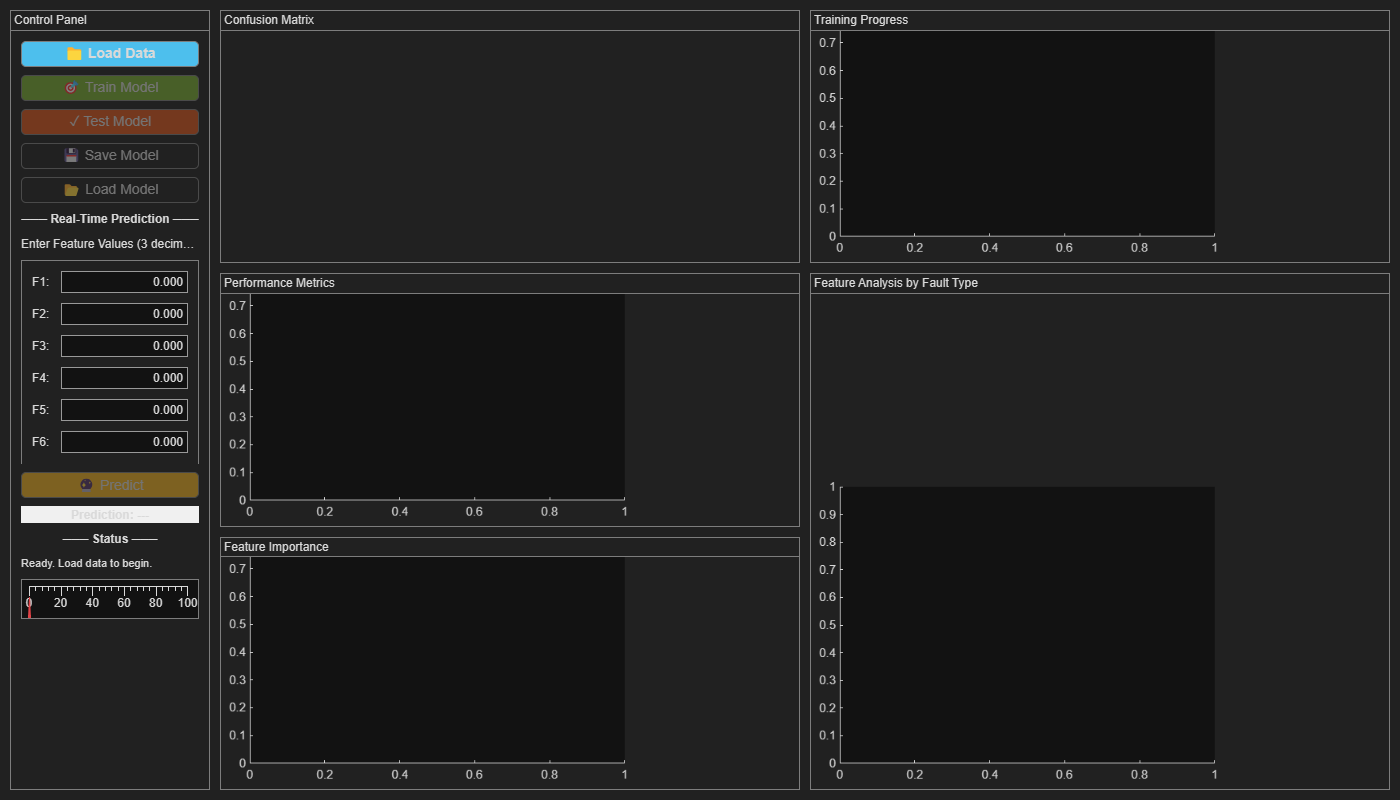

GUI created successfully!



% Create main GUI
createMainGUI();


%% Function: Create Main GUI
function createMainGUI()
    global fig
    
    fig = uifigure('Name', 'Fault Detection System', ...
                   'Position', [50 50 1400 800]);
    
    % Main grid layout
    mainGrid = uigridlayout(fig, [3, 3]);
    mainGrid.RowHeight = {'1x', '1x', '1x'};
    mainGrid.ColumnWidth = {200, '1x', '1x'};
    
    %% Left Panel - Controls
    controlPanel = uipanel(mainGrid, 'Title', 'Control Panel');
    controlPanel.Layout.Row = [1 3];
    controlPanel.Layout.Column = 1;
    
    controlGrid = uigridlayout(controlPanel, [15, 1]);
    controlGrid.RowHeight = repmat({'fit'}, 1, 15);
    controlGrid.Padding = [10 10 10 10];
    controlGrid.RowSpacing = 8;
    
    % Buttons
    btnLoad = uibutton(controlGrid, 'Text', '📁 Load Data', ...
        'FontSize', 14, 'FontWeight', 'bold', ...
        'BackgroundColor', [0.3 0.75 0.93]);
    btnLoad.ButtonPushedFcn = @(~,~) loadDataCallback();
    
    btnTrain = uibutton(controlGrid, 'Text', '🎯 Train Model', ...
        'FontSize', 14, 'Enable', 'off', ...
        'BackgroundColor', [0.47 0.67 0.19]);
    btnTrain.ButtonPushedFcn = @(~,~) trainModelCallback(btnTrain);
    
    btnTest = uibutton(controlGrid, 'Text', '✓ Test Model', ...
        'FontSize', 14, 'Enable', 'off', ...
        'BackgroundColor', [0.85 0.33 0.10]);
    btnTest.ButtonPushedFcn = @(~,~) testModelCallback(btnTest);
    
    btnSave = uibutton(controlGrid, 'Text', '💾 Save Model', ...
        'FontSize', 14, 'Enable', 'off');
    btnSave.ButtonPushedFcn = @(~,~) saveModelCallback();
    
    btnLoadModel = uibutton(controlGrid, 'Text', '📂 Load Model', ...
        'FontSize', 14, 'Enable', 'off');
    btnLoadModel.ButtonPushedFcn = @(~,~) loadModelCallback(btnTrain, btnTest, btnSave);
    
    % Separator
    uilabel(controlGrid, 'Text', '─── Real-Time Prediction ───', ...
        'FontWeight', 'bold', 'HorizontalAlignment', 'center');
    
    % Prediction input fields with helper text
    uilabel(controlGrid, 'Text', 'Enter Feature Values (3 decimals):');
    
    % Create input fields with 3 decimal precision
    inputPanel = uipanel(controlGrid);
    inputPanel.Layout.Row = 8;
    inputGrid = uigridlayout(inputPanel, [6, 2]);
    inputGrid.ColumnWidth = {'fit', '1x'};
    inputGrid.RowHeight = repmat({22}, 1, 6);
    
    % Store edit fields with 3 decimal precision
    editFields = cell(6, 1);
    for i = 1:6
        uilabel(inputGrid, 'Text', sprintf('F%d:', i));
        editFields{i} = uieditfield(inputGrid, 'numeric', ...
            'Value', 0, ...
            'ValueDisplayFormat', '%.3f', ...
            'Limits', [-Inf Inf]);
    end
    
    btnPredict = uibutton(controlGrid, 'Text', '🔮 Predict', ...
        'FontSize', 14, 'Enable', 'off', ...
        'BackgroundColor', [0.93 0.69 0.13]);
    btnPredict.ButtonPushedFcn = @(~,~) predictCallback(editFields);
    
    % Prediction result (Larger, more visible)
    lblPrediction = uilabel(controlGrid, 'Text', 'Prediction: ---', ...
        'FontSize', 12, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center', ...
        'BackgroundColor', [0.94 0.94 0.94], ...
        'WordWrap', 'on');
    
    % Separator
    uilabel(controlGrid, 'Text', '─── Status ───', ...
        'FontWeight', 'bold', 'HorizontalAlignment', 'center');
    
    % Status display
    lblStatus = uilabel(controlGrid, 'Text', 'Ready. Load data to begin.', ...
        'FontSize', 11, 'WordWrap', 'on');
    
    % Progress gauge
    gaugeProgress = uigauge(controlGrid, 'linear', ...
        'Limits', [0 100], 'Value', 0);
    
    % Store UI components for callbacks
    setappdata(fig, 'btnTrain', btnTrain);
    setappdata(fig, 'btnTest', btnTest);
    setappdata(fig, 'btnSave', btnSave);
    setappdata(fig, 'btnLoadModel', btnLoadModel);
    setappdata(fig, 'btnPredict', btnPredict);
    setappdata(fig, 'lblStatus', lblStatus);
    setappdata(fig, 'lblPrediction', lblPrediction);
    setappdata(fig, 'gaugeProgress', gaugeProgress);
    setappdata(fig, 'editFields', editFields);
    
    %% Right Panels - Visualizations
    
    % Panel 1: Confusion Matrix (FIXED - use panel directly, not uiaxes)
    pnlConfusion = uipanel(mainGrid, 'Title', 'Confusion Matrix');
    pnlConfusion.Layout.Row = 1;
    pnlConfusion.Layout.Column = 2;
    setappdata(fig, 'pnlConfusion', pnlConfusion);
    
    % Panel 2: Training Error
    pnlTraining = uipanel(mainGrid, 'Title', 'Training Progress');
    pnlTraining.Layout.Row = 1;
    pnlTraining.Layout.Column = 3;
    axTraining = uiaxes(pnlTraining);
    setappdata(fig, 'axTraining', axTraining);
    
    % Panel 3: Metrics
    pnlMetrics = uipanel(mainGrid, 'Title', 'Performance Metrics');
    pnlMetrics.Layout.Row = 2;
    pnlMetrics.Layout.Column = 2;
    axMetrics = uiaxes(pnlMetrics);
    setappdata(fig, 'axMetrics', axMetrics);
    
    % Panel 4: Feature Analysis
    pnlFeatures = uipanel(mainGrid, 'Title', 'Feature Analysis by Fault Type');
    pnlFeatures.Layout.Row = [2 3];
    pnlFeatures.Layout.Column = 3;
    axFeatures = uiaxes(pnlFeatures);
    setappdata(fig, 'axFeatures', axFeatures);
    
    % Panel 5: Feature Importance
    pnlImportance = uipanel(mainGrid, 'Title', 'Feature Importance');
    pnlImportance.Layout.Row = 3;
    pnlImportance.Layout.Column = 2;
    axImportance = uiaxes(pnlImportance);
    setappdata(fig, 'axImportance', axImportance);
    
    disp('GUI created successfully!');
end

%% Callback: Load Data
function loadDataCallback()
    global XTrain YTrain XTest YTest featureNames mu sigma fig
    
    lblStatus = getappdata(fig, 'lblStatus');
    gaugeProgress = getappdata(fig, 'gaugeProgress');
    btnTrain = getappdata(fig, 'btnTrain');
    btnLoadModel = getappdata(fig, 'btnLoadModel');
    
    try
        lblStatus.Text = 'Selecting files...';
        gaugeProgress.Value = 5;
        drawnow;
        
        % File selection
        [filenames, pathname] = uigetfile('*.csv', ...
            'Select Fault Detection Datasets', 'MultiSelect', 'on');
        
        if isequal(filenames, 0)
            lblStatus.Text = 'File selection cancelled.';
            gaugeProgress.Value = 0;
            return;
        end
        
        if ischar(filenames)
            filenames = {filenames};
        end
        
        lblStatus.Text = sprintf('Loading %d files...', length(filenames));
        gaugeProgress.Value = 20;
        drawnow;
        
        % EFFICIENT LOADING: Use cell array instead of growing array
        dataCell = cell(length(filenames), 1);
        for i = 1:length(filenames)
            fullpath = fullfile(pathname, filenames{i});
            opts = detectImportOptions(fullpath);
            opts.VariableNamingRule = 'preserve';
            dataCell{i} = readtable(fullpath, opts);
        end
        
        % Efficient concatenation
        fullData = vertcat(dataCell{:});
        gaugeProgress.Value = 50;
        
        % Preprocessing
        lblStatus.Text = 'Preprocessing data...';
        fullData = rmmissing(fullData);
        
        featureNames = fullData.Properties.VariableNames(1:6);
        X = fullData{:, 1:6};
        Y = categorical(fullData{:, 7});
        
        % Split data FIRST (70-30 split)
        cv = cvpartition(Y, 'HoldOut', 0.3);
        gaugeProgress.Value = 10;

        idxTrain = training(cv);
        idxTest = test(cv);

        % Keep original-scale data for train/test
        XTrainRaw = X(idxTrain, :);
        XTestRaw = X(idxTest, :);
        
        gaugeProgress.Value = 40;

        YTrain = Y(idxTrain);
        YTest = Y(idxTest);

        % Calculate normalization statistics ONLY from training data
        mu = mean(XTrainRaw, 1);
        sigma = std(XTrainRaw, 0, 1);
        
        gaugeProgress.Value = 70;

        % Prevent division by zero for constant features
        sigma(sigma == 0) = 1;

        % Normalize training and testing data using TRAINING statistics
        XTrain = (XTrainRaw - mu) ./ sigma;
        XTest = (XTestRaw - mu) ./ sigma;
        
        gaugeProgress.Value = 100;
        lblStatus.Text = sprintf('✓ Data loaded: %d training, %d test samples', ...
            length(YTrain), length(YTest));
        
        % Enable buttons
        btnTrain.Enable = 'on';
        btnLoadModel.Enable = 'on';
        
        % Update input field labels
        updateInputLabels();
        
        disp('Data loading complete!');
        disp(['Unique classes: ' strjoin(string(categories(Y)), ', ')]);

    catch ME
        lblStatus.Text = ['Error: ' ME.message];
        gaugeProgress.Value = 0;
        uialert(fig, ME.message, 'Data Loading Error');
    end
end

%% Callback: Train Model
function trainModelCallback(btnTrain)
    global rfModel XTrain YTrain featureNames fig
    
    lblStatus = getappdata(fig, 'lblStatus');
    gaugeProgress = getappdata(fig, 'gaugeProgress');
    btnTest = getappdata(fig, 'btnTest');
    btnSave = getappdata(fig, 'btnSave');
    btnPredict = getappdata(fig, 'btnPredict');
    axTraining = getappdata(fig, 'axTraining');
    axImportance = getappdata(fig, 'axImportance');
    
    try
        btnTrain.Enable = 'off';
        lblStatus.Text = 'Training Random Forest model...';
        gaugeProgress.Value = 0;
        drawnow;
        
        numTrees = 20;
        gaugeProgress.Value = 20;
        
        rfModel = TreeBagger(numTrees, XTrain, YTrain, ...
            'Method', 'classification', ...
            'OOBPrediction', 'on', ...
            'MinLeafSize', 500, ...
            'PredictorNames', featureNames, ...
            'OOBPredictorImportance', 'on');
        
        gaugeProgress.Value = 80;
        
        % Plot training error
        oobErr = oobError(rfModel);
        plot(axTraining, oobErr, 'LineWidth', 2.5, 'Color', [0.85 0.33 0.10]);
        xlabel(axTraining, 'Number of Trees', 'FontSize', 11);
        ylabel(axTraining, 'Out-of-Bag Error', 'FontSize', 11);
        title(axTraining, 'Training Error Progression', 'FontSize', 12, 'FontWeight', 'bold');
        grid(axTraining, 'on');
        
        % Plot feature importance
        importance = rfModel.OOBPermutedPredictorDeltaError;
        bar(axImportance, importance, 'FaceColor', [0.3 0.75 0.93]);
        axImportance.XTickLabel = featureNames;
        xtickangle(axImportance, 45);
        ylabel(axImportance, 'Importance Score', 'FontSize', 11);
        title(axImportance, 'Feature Importance Ranking', 'FontSize', 12, 'FontWeight', 'bold');
        grid(axImportance, 'on');
        
        gaugeProgress.Value = 100;
        lblStatus.Text = '✓ Model training complete!';
        
        % Enable buttons
        btnTest.Enable = 'on';
        btnSave.Enable = 'on';
        btnPredict.Enable = 'on';
        btnTrain.Enable = 'on';
        
        disp('Model training complete!');
        
    catch ME
        lblStatus.Text = ['Training error: ' ME.message];
        btnTrain.Enable = 'on';
        gaugeProgress.Value = 0;
        uialert(fig, ME.message, 'Training Error');
    end
end

%% Callback: Test Model
function testModelCallback(btnTest)
    global rfModel XTest YTest XTrain YTrain mu sigma featureNames fig
    
    lblStatus = getappdata(fig, 'lblStatus');
    pnlConfusion = getappdata(fig, 'pnlConfusion');
    axMetrics = getappdata(fig, 'axMetrics');
    axFeatures = getappdata(fig, 'axFeatures');
    
    try
        btnTest.Enable = 'off';
        lblStatus.Text = 'Testing model...';
        drawnow;
        
        % Predict
        [YPred, ~] = predict(rfModel, XTest);
        YPred = categorical(YPred);
        
        % Calculate accuracy
        accuracy = sum(YPred == YTest) / numel(YTest) * 100;
        
        % Confusion matrix
        confMat = confusionmat(YTest, YPred);
        
        % FIXED: Clear panel and create confusion chart directly in panel
        delete(pnlConfusion.Children);  % Clear previous content
        cm = confusionchart(pnlConfusion, YTest, YPred);
        cm.Title = sprintf('Accuracy: %.2f%%', accuracy);
        cm.FontSize = 11;
        
        % Calculate and plot metrics
        classes = categories(YTest);
        numClasses = length(classes);
        precision = zeros(numClasses, 1);
        recall = zeros(numClasses, 1);
        f1score = zeros(numClasses, 1);
        
        for i = 1:numClasses
            TP = confMat(i, i);
            FP = sum(confMat(:, i)) - TP;
            FN = sum(confMat(i, :)) - TP;
            
            precision(i) = TP / max(TP + FP, 1);
            recall(i) = TP / max(TP + FN, 1);
            f1score(i) = 2 * (precision(i) * recall(i)) / max(precision(i) + recall(i), eps);
        end
        
        % FIXED: Plot metrics properly
        cla(axMetrics);
        metrics = [precision, recall, f1score] * 100;
        b = bar(axMetrics, metrics);
        b(1).FaceColor = [0.2 0.6 0.8];
        b(2).FaceColor = [0.8 0.4 0.2];
        b(3).FaceColor = [0.4 0.8 0.2];
        
        axMetrics.XTickLabel = classes;
        xtickangle(axMetrics, 45);
        ylabel(axMetrics, 'Score (%)', 'FontSize', 11);
        title(axMetrics, 'Performance Metrics by Class', 'FontSize', 12, 'FontWeight', 'bold');
        legend(axMetrics, {'Precision', 'Recall', 'F1-Score'}, ...
            'Location', 'best', 'FontSize', 10);
        grid(axMetrics, 'on');
        ylim(axMetrics, [0 105]);
        
        % FIXED: Feature analysis
        cla(axFeatures);
        meanValues = zeros(6, numClasses);
        XOriginal = XTrain .* sigma + mu;
        
        for c = 1:numClasses
            idx = (YTrain == classes(c));
            meanValues(:, c) = mean(XOriginal(idx, :), 1)';
        end
        
        b2 = bar(axFeatures, meanValues);
        % Assign different colors to each class
        colors = lines(numClasses);
        for i = 1:numClasses
            b2(i).FaceColor = colors(i,:);
        end
        
        axFeatures.XTickLabel = featureNames;
        xtickangle(axFeatures, 45);
        ylabel(axFeatures, 'Mean Value', 'FontSize', 11);
        title(axFeatures, 'Average Feature Values per Class', 'FontSize', 12, 'FontWeight', 'bold');
        legend(axFeatures, string(classes), 'Location', 'bestoutside', 'FontSize', 10);
        grid(axFeatures, 'on');
        
        lblStatus.Text = sprintf('✓ Testing complete! Accuracy: %.2f%% | Avg F1: %.2f%%', ...
            accuracy, mean(f1score)*100);
        
        btnTest.Enable = 'on';
        
        disp('====================================');
        disp(['Test Accuracy: ' num2str(accuracy, '%.2f') '%']);
        disp('Per-class metrics:');
        for i = 1:numClasses
            fprintf('%s - Precision: %.2f%%, Recall: %.2f%%, F1: %.2f%%\n', ...
                string(classes(i)), precision(i)*100, recall(i)*100, f1score(i)*100);
        end
        disp('====================================');
        
    catch ME
        lblStatus.Text = ['Testing error: ' ME.message];
        btnTest.Enable = 'on';
        uialert(fig, ME.message, 'Testing Error');
        disp(['Error: ' ME.message]);
    end
end

%% Callback: Save Model
function saveModelCallback()
    global rfModel featureNames mu sigma fig
    
    lblStatus = getappdata(fig, 'lblStatus');
    
    try
        [file, path] = uiputfile('*.mat', 'Save Trained Model');
        if ~isequal(file, 0)
            save(fullfile(path, file), 'rfModel', 'featureNames', 'mu', 'sigma');
            lblStatus.Text = ['✓ Model saved: ' file];
            disp(['Model saved to: ' fullfile(path, file)]);
        end
    catch ME
        uialert(fig, ME.message, 'Save Error');
    end
end

%% Callback: Load Model
function loadModelCallback(btnTrain, btnTest, btnSave)
    global rfModel featureNames mu sigma fig
    
    lblStatus = getappdata(fig, 'lblStatus');
    btnPredict = getappdata(fig, 'btnPredict');
    
    try
        [file, path] = uigetfile('*.mat', 'Load Trained Model');
        if ~isequal(file, 0)
            loaded = load(fullfile(path, file));
            rfModel = loaded.rfModel;
            featureNames = loaded.featureNames;
            mu = loaded.mu;
            sigma = loaded.sigma;
            
            btnTrain.Enable = 'on';
            btnTest.Enable = 'on';
            btnSave.Enable = 'on';
            btnPredict.Enable = 'on';
            
            lblStatus.Text = ['✓ Model loaded: ' file];
            updateInputLabels();
            disp(['Model loaded from: ' fullfile(path, file)]);
        end
    catch ME
        uialert(fig, ME.message, 'Load Error');
    end
end

%% Callback: Predict - CONFIDENCE REMOVED, TYPE 1 GREEN BOX (console probabilities removed)
function predictCallback(editFields)
    global rfModel mu sigma YTrain fig
    
    lblStatus = getappdata(fig, 'lblStatus');
    lblPrediction = getappdata(fig, 'lblPrediction');
    
    try
        % Get input values (with 3 decimal precision)
        inputValues = zeros(1, 6);
        for i = 1:6
            inputValues(i) = editFields{i}.Value;
        end
        
        % Normalize using training statistics
        inputNorm = (inputValues - mu) ./ sigma;
        
        % Predict (no scores requested)
        prediction = predict(rfModel, inputNorm);
        
        % Get predicted class
        predClass = prediction{1};
        predStr = char(predClass);
        
        % Determine if it's a fault based on Type 1 or Type 2
        if strcmp(predStr, '1') || contains(predStr, 'Type 1')
            % Type 1 = Normal
            faultStatus = '✅ NORMAL - No Fault Detected';
            statusColor = [0 0.5 0]; % Green font
            lblPrediction.BackgroundColor = [0.85 1.0 0.85]; % Light green box
            displayType = 'No Fault';
        elseif strcmp(predStr, '2') || contains(predStr, 'Type 2')
            % Type 2 = Fault
            faultStatus = '⚠️ FAULT DETECTED';
            statusColor = [0.8 0 0]; % Red font
            lblPrediction.BackgroundColor = [1 0.9 0.9]; % Light red box
            displayType = 'Fault Present';
        else
            % If other types exist, treat as fault
            faultStatus = '⚠️ FAULT DETECTED';
            statusColor = [0.8 0 0]; % Red font
            lblPrediction.BackgroundColor = [1 0.9 0.9]; % Light red box
            displayType = predStr;
        end
        
        % Display comprehensive result (NO confidence shown in UI)
        lblPrediction.Text = sprintf('%s\n%s', faultStatus, displayType);
        lblPrediction.FontColor = statusColor;
        
        lblStatus.Text = '✓ Prediction complete!';
        
        % Console output with input values (NO per-class probabilities)
        disp('====================================');
        disp('PREDICTION RESULT:');
        disp('Input Values:');
        for i = 1:6
            fprintf('  Feature %d: %.3f\n', i, inputValues(i));
        end
        disp(' ');
        disp(['Status: ' faultStatus]);
        disp(['Classification: ' displayType]);
        disp('====================================');
        
    catch ME
        lblStatus.Text = ['Prediction error: ' ME.message];
        lblPrediction.Text = 'Error in prediction';
        lblPrediction.FontColor = [0.8 0 0];
        uialert(fig, ME.message, 'Prediction Error');
    end
end

%% Helper: Update Input Labels
function updateInputLabels()
    global featureNames fig
    
    editFields = getappdata(fig, 'editFields');
    if ~isempty(featureNames) && ~isempty(editFields)
        for i = 1:min(6, length(featureNames))
            editFields{i}.Tooltip = featureNames{i};
        end
    end
end